## 1. Motor Parameters 


clear all
clc
R=18.2214;
L=0.000866;
Kb=0.030941093;
Km=0.030941093;
J=0.00009;
B1=0.000025;

## 2. State Space Model


% state Space Matrices

A=[0        1       0
   0        -B1/J    Km/J
   0        -Kb/L   -R/L];

B=[0
   0
  1/L];

C=[1  0  0];

D=[0];

% Create the continuos time state space Model
Continuous_Plant_Model=ss(A,B,C,D);
d_sys = c2d(Continuous_Plant_Model,0.1);
fprintf('Continous Time Plant Model \n');

Continous Time Plant Model 


save d_sys.mat

## 3. Simulation 

sim Dual_Axis_Solar_Tracker

   Assuming no disturbance added to measured output #1.


## **4. Graph data**

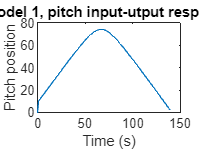

figure(1);plot(t,model1); % raw speed measurements
title('Model 1, pitch input-utput response');
xlabel('Time (s)');
ylabel('Pitch position');

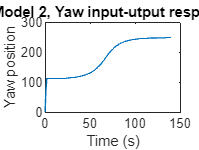

figure(2);plot(t,model2); % raw speed measurements
title('Model 2, Yaw input-utput response');
xlabel('Time (s)');
ylabel('Yaw position');